# File for the figures of the paper

The figures presented are based on bayesian statistics calibrated parameters that were performed with the toolbox DREAM. The package is only for private use, and the specific configuration used to run DREAM with the model versions can be provided upon request. The outputs are as well very heavy and available upon request. 

## Figure 2

We present the procedure to calculate the figure 2 of the paper as well as supplementary figure S4. Files for running this figure are available upon request. Final editing of the figure was done with the software Inkscape. 

### Atrazine

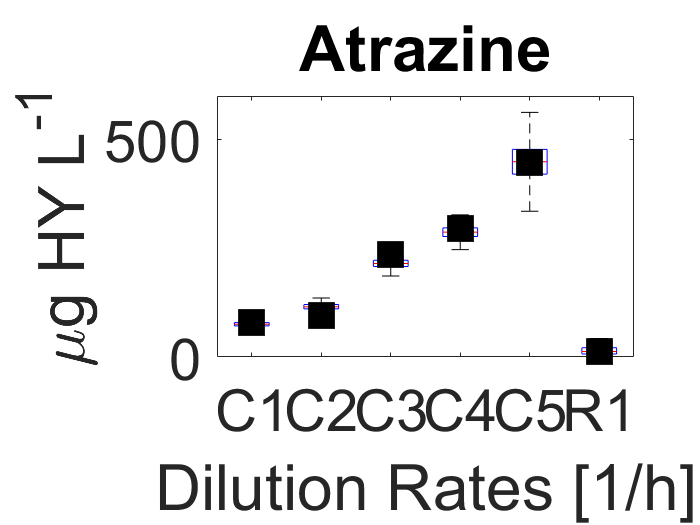

% Calling Data Chemostat %

load('chemostat_data.txt')
EF_C  = -5.36;
sd_C  = 0.2;
Datam = chemostat_data(:,1);
Datas = chemostat_data(:,2);

DAT_C   = vertcat(Datam(1:10),Datam(11:15));
DAT_Csd = vertcat(Datas(1:10),Datas(11:15));

% Calling Data Retentostat %

load('retentostat_data.txt')

DatamR   = retentostat_data(:,1);
DatasR   = retentostat_data(:,2);

DAT_R    = vertcat(DatamR(1:2),DatamR(3));
DAT_Rsd  = vertcat(DatasR(1:2),DatasR(3));
EF_R     = -0.45;
sd_R     = 0.36;

% Calling Simulations %

% Chemostat %

load('Final_AT1.mat')
load('Final_AT2.mat')
load('Final_AT3.mat')
load('Final_AT4.mat')
load('Final_AT5.mat')

DL1    = {};
DL2    = {};
DL3    = {};
DL4    = {};
DL5    = {};

for i = 1:length(Final_AT1)
    DL1{end+1} = Final_AT1{i}(end);
    DL2{end+1} = Final_AT2{i}(end);
    DL3{end+1} = Final_AT3{i}(end);
    DL4{end+1} = Final_AT4{i}(end);
    DL5{end+1} = Final_AT5{i}(end);
end

A = cell2mat(DL1)';
B = cell2mat(DL2)';
C = cell2mat(DL3)';
D = cell2mat(DL4)';
E = cell2mat(DL5)';

% Retentostat %

load('Final_AT1R.mat')

DL1R    = {};

for i = 1:length(Final_AT1R)
    DL1R{end+1} = Final_AT1R{i}(end);
end

A1r = cell2mat(DL1R)';

x = [A; B; C; D; E; A1r];

g1 = repmat({'C1'},13987,1);
g2 = repmat({'C2'},13987,1);
g3 = repmat({'C3'},13987,1);
g4 = repmat({'C4'},13987,1);
g5 = repmat({'C5'},13987,1);
g6 = repmat({'R1'},13987,1);

g = [g1; g2; g3; g4; g5; g6];

% Plotting %

figure
AH = boxplot(x,g,'symbol','');
hold on
B = plot(vertcat(DAT_C(1:5),DAT_R(1)),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
ylim([0 6e2])
set(gca,'FontSize',35)
xlabel('Dilution Rates [1/h]')
ylabel('\mug HY L^{-1}')
title('Atrazine')
box on
hold off

### Hydroxyatrazine

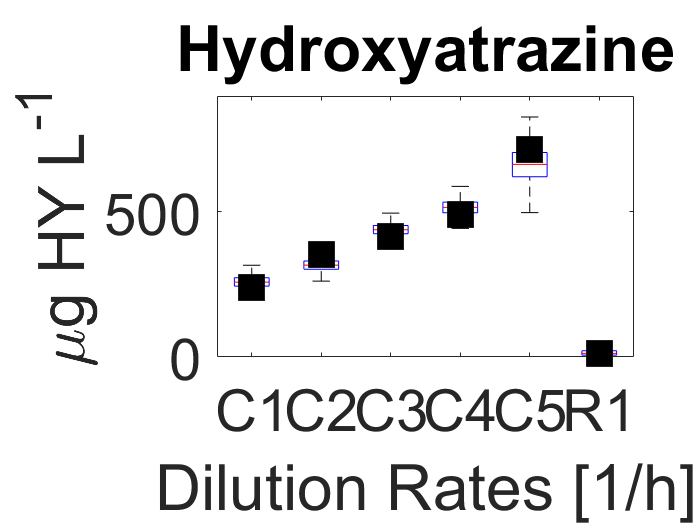

% Calling Simulations %

% Chemostat %

load('Final_HY1.mat')
load('Final_HY2.mat')
load('Final_HY3.mat')
load('Final_HY4.mat')
load('Final_HY5.mat')

DL1H    = {};
DL2H    = {};
DL3H    = {};
DL4H    = {};
DL5H    = {};

for i = 1:length(Final_HY1)
    DL1H{end+1} = Final_HY1{i}(end);
    DL2H{end+1} = Final_HY2{i}(end);
    DL3H{end+1} = Final_HY3{i}(end);
    DL4H{end+1} = Final_HY4{i}(end);
    DL5H{end+1} = Final_HY5{i}(end);
end

AH = cell2mat(DL1H)';
BH = cell2mat(DL2H)';
CH = cell2mat(DL3H)';
DH = cell2mat(DL4H)';
EH = cell2mat(DL5H)';

% Retentostat %

load('Final_HY1R.mat')

DL2R    = {};

for i = 1:length(Final_HY1R)
    DL2R{end+1} = Final_HY1R{i}(end);
end

A2a = cell2mat(DL2R)';

xH = [AH; BH; CH; DH; EH; A2a];

g1H = repmat({'C1'},13987,1);
g2H = repmat({'C2'},13987,1);
g3H = repmat({'C3'},13987,1);
g4H = repmat({'C4'},13987,1);
g5H = repmat({'C5'},13987,1);
g6H = repmat({'R1'},13987,1);

gH= [g1H; g2H; g3H; g4H; g5H; g6H];

% Plotting %

figure
AH = boxplot(xH,gH,'symbol','');
hold on
BH = plot(vertcat(DAT_C(6:10),DAT_R(2)),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
xlabel('Dilution Rates [1/h]')
ylabel('\mug HY L^{-1}')
title('Hydroxyatrazine')
ylim([0 9e2])
set(gca,'FontSize',35)
box on
hold off

### Biomass

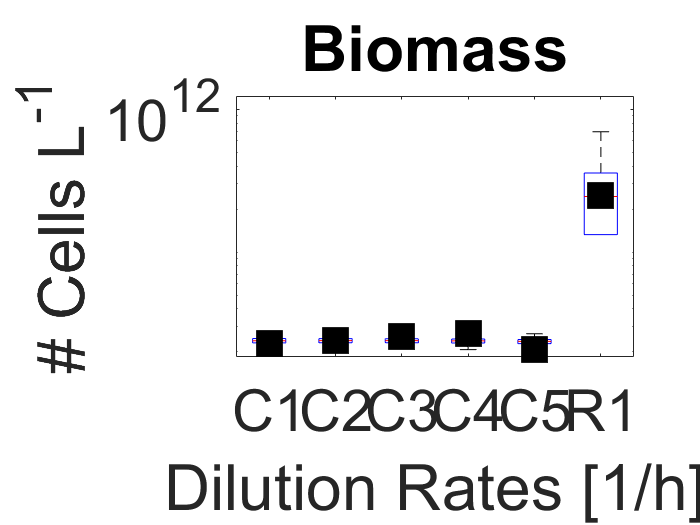

% Calling Simulations %

% Chemostat %

load('Final_Bio1.mat')
load('Final_Bio2.mat')
load('Final_Bio3.mat')
load('Final_Bio4.mat')
load('Final_Bio5.mat')

DL1c    = {};
DL2c    = {};
DL3c    = {};
DL4c    = {};
DL5c    = {};

for i = 1:length(Final_Bio1)
    DL1c{end+1} = Final_Bio1{i}(end);
    DL2c{end+1} = Final_Bio2{i}(end);
    DL3c{end+1} = Final_Bio3{i}(end);
    DL4c{end+1} = Final_Bio4{i}(end);
    DL5c{end+1} = Final_Bio5{i}(end);
end

Ac = cell2mat(DL1c)';
Bc = cell2mat(DL2c)';
Cc = cell2mat(DL3c)';
Dc = cell2mat(DL4c)';
Ec = cell2mat(DL5c)';

% Retentostat %

load('Final_Bio1R.mat')

DL3R    = {};

for i = 1:length(Final_Bio1R)
    DL3R{end+1} = Final_Bio1R{i}(end);
end

A3a = cell2mat(DL3R)';

xc = [Ac; Bc; Cc; Dc; Ec; A3a];

g1c = repmat({'C1'},13987,1);
g2c = repmat({'C2'},13987,1);
g3c = repmat({'C3'},13987,1);
g4c = repmat({'C4'},13987,1);
g5c = repmat({'C5'},13987,1);
g6c = repmat({'R1'},13987,1);

gc= [g1c; g2c; g3c; g4c; g5c; g6c];

% Plotting %

figure
Ac = boxplot(xc,gc,'symbol','');
hold on
Bc = plot(vertcat(DAT_C(11:15),DAT_R(3)),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
xlabel('Dilution Rates [1/h]')
ylabel('# Cells L^{-1}')
title('Biomass')
set(gca,'FontSize',35,'YScale', 'log')
box on
hold off

### Enrichment Factor

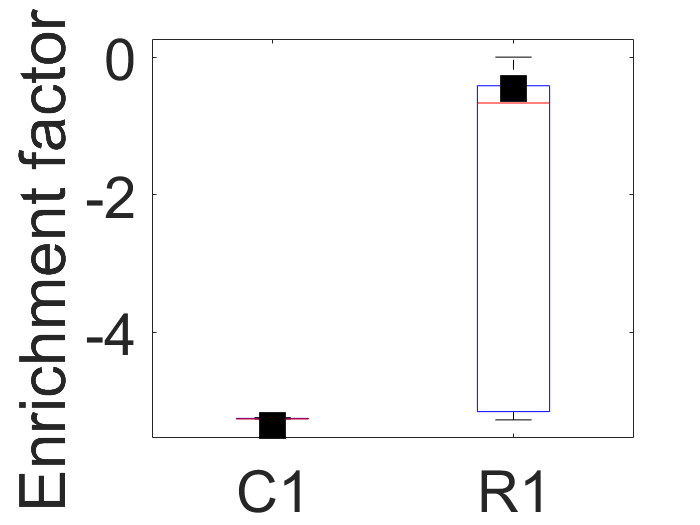

% Calling Simulations %

% Chemostat %

load('F_EF_Ch.mat')

DLefc    = {};

for i = 1:length(F_EF_Ch)
    DLefc{end+1} = F_EF_Ch{i}(end);
end

Aefcc = cell2mat(DLefc)';

% Retentostat %

load('F_EF_Rt.mat')

DLefr    = {};

for i = 1:length(F_EF_Rt)
    DLefr{end+1} = F_EF_Rt{i}(end);
end

Aefrc = cell2mat(DLefr)';

% Plotting %

xc  = [Aefcc; Aefrc];
g1e = repmat({'C1'},13987,1);
g6e = repmat({'R1'},13987,1);

gc= [g1e; g6e];

figure
Ac = boxplot(xc,gc,'symbol','');
hold on
Bc = plot(vertcat(EF_C,EF_R),'s','MarkerSize',20,'MarkerFaceColor','k','MarkerEdgeColor','k');
ylabel('Enrichment factor \epsilon')
set(gca,'FontSize',35)
box on
hold off

## Figure 4

We present the procedure to calculate the figure 4 of the paper. Files for running this figure are available upon request. Final editing of the figure was done with the software Inkscape. 

### Atrazine residual concentration after 30 years

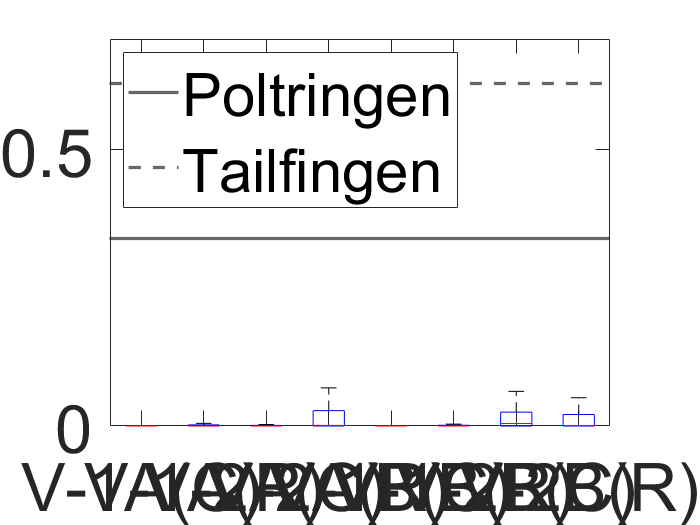

% Time Vector for 30 years %

t_base  = linspace(0,10950,1000);

% Calling Simulations %

% Chemostat %

load('total_AT_CH_T.mat') % Thermodynamic no leaching
load('Time_CH_T.mat')

vq1     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq1{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end


load('Time_CH_M.mat') % Monod no leaching
load('total_AT_CH_M.mat')

vq2     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq2{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_CH_T_L.mat') % Thermodynamic leaching
load('total_AT_CH_T_L.mat')

vq3     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq3{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_CH_M_L.mat') % Monod leaching
load('total_AT_CH_M_L.mat')

vq4     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq4{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

% Retentostat %

load('total_AT_RT_T.mat')
load('Time_RT_T.mat')

vq1r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq1r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_RT_M.mat')
load('total_AT_RT_M.mat')

vq2r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq2r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_RT_T_L.mat')
load('total_AT_RT_T_L.mat')

vq3r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq3r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_RT_M_L.mat')
load('total_AT_RT_M_L.mat')

vq4r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_AT(i));
    vq4r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

% End Points Determination %

AT_CH_T      = {};
for i = 1:length(vq1)
    AT_CH_T{end+1} = vq1{i}(end);
end
A = cell2mat(AT_CH_T)'; 

AT_RT_T      = {};
for i = 1:length(vq1r)
    AT_RT_T{end+1} = vq1r{i}(end);
end
Ar = cell2mat(AT_RT_T)'; 

AT_CH_M      = {};
for i = 1:length(vq2)
    AT_CH_M{end+1} = vq2{i}(end);
end
B = cell2mat(AT_CH_M)'; 

AT_RT_M      = {};
for i = 1:length(vq2r)
    AT_RT_M{end+1} = vq2r{i}(end);
end
Br = cell2mat(AT_RT_M)'; 

AT_CH_T_L    = {};
for i = 1:length(vq3)
    AT_CH_T_L{end+1} = vq3{i}(end);
end
C = cell2mat(AT_CH_T_L)'; 

AT_RT_T_L    = {};
for i = 1:length(vq3r)
    AT_RT_T_L{end+1} = vq3r{i}(end);
end
Cr = cell2mat(AT_RT_T_L)'; 

AT_CH_M_L    = {};
for i = 1:length(vq4)
    AT_CH_M_L{end+1} = vq4{i}(end);
end
D = cell2mat(AT_CH_M_L)'; 

AT_RT_M_L    = {};
for i = 1:length(vq4r)
    AT_RT_M_L{end+1} = vq4r{i}(end);
end
Dr = cell2mat(AT_RT_M_L)'; 

% Plotting %

PoltringenA = 0.34;
TailfingenA = 0.62;

xs    = [B; Br;A; Ar;D; Dr;C; Cr];

g1s = repmat({'V-1A(C)'},13987,1);
g2s = repmat({'V-1A(R)'},13987,1);
g3s = repmat({'V-2A(C)'},13987,1);
g4s = repmat({'V-2A(R)'},13987,1);
g5s = repmat({'V-1B(C)'},13987,1);
g6s = repmat({'V-1B(R)'},13987,1);
g7s = repmat({'V-2B(C)'},13987,1);
g8s = repmat({'V-2B(R)'},13987,1);

gs  = [g1s;g2s;g3s;g4s;g5s;g6s;g7s;g8s];

figure
Ac = boxplot(xs,gs,'symbol','');
hold on
P = yline(PoltringenA,'-','LineWidth',2);
T = yline(TailfingenA,'--','LineWidth',2);
legend([P T],'Poltringen','Tailfingen','Location','northwest')
set(gca,'FontSize',40,'TickLength',[0.030 0.015])
ylim([0 0.7])
box on
hold off

### Hydroxyatrazine residual concentration after 30 years

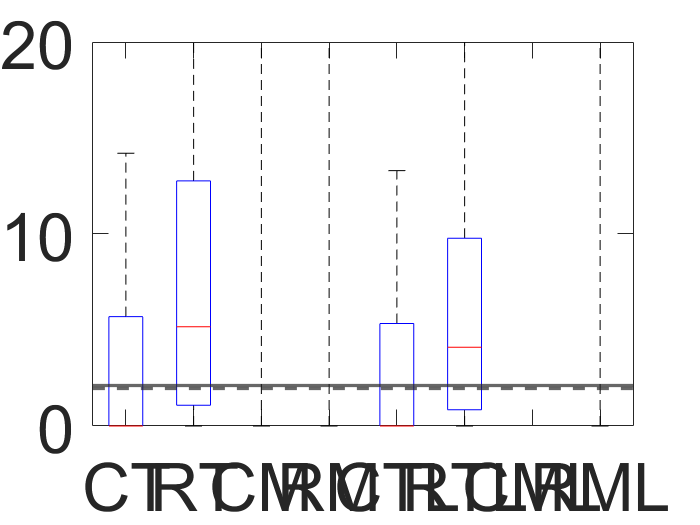

% Time Vector for 30 years %

t_base  = linspace(0,10950,1000);

% Calling Simulations %

% Chemostat %

load('total_HY_CH_T.mat') % Thermodynamic no leaching
load('Time_CH_T.mat')

vq1     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq1{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end


load('Time_CH_M.mat') % Monod no leaching
load('total_HY_CH_M.mat')

vq2     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq2{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_CH_T_L.mat') % Thermodynamic leaching
load('total_HY_CH_T_L.mat')

vq3     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq3{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_CH_M_L.mat') % Monod leaching
load('total_HY_CH_M_L.mat')

vq4     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq4{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

% Retentostat %

load('total_HY_RT_T.mat')
load('Time_RT_T.mat')

vq1r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq1r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_RT_M.mat')
load('total_HY_RT_M.mat')

vq2r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq2r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_RT_T_L.mat')
load('total_HY_RT_T_L.mat')

vq3r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq3r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

load('Time_RT_M_L.mat')
load('total_HY_RT_M_L.mat')

vq4r     = {};

for i=1:length(Time)
    [x, index]  = unique(cell2mat(Time(i))); 
    DNAacA      = cell2mat(total_HY(i));
    vq4r{end+1}  = (interp1(x,DNAacA(index),t_base,'linear'))';
end

% End Points Determination %

HY_CH_T      = {};
for i = 1:length(vq1)
    HY_CH_T{end+1} = vq1{i}(end);
end
A = cell2mat(HY_CH_T)'; 

HY_RT_T      = {};
for i = 1:length(vq1r)
    HY_RT_T{end+1} = vq1r{i}(end);
end
Ar = cell2mat(HY_RT_T)'; 

HY_CH_M      = {};
for i = 1:length(vq2)
    HY_CH_M{end+1} = vq2{i}(end);
end
B = cell2mat(HY_CH_M)'; 

HY_RT_M      = {};
for i = 1:length(vq2r)
    HY_RT_M{end+1} = vq2r{i}(end);
end
Br = cell2mat(HY_RT_M)'; 

HY_CH_T_L    = {};
for i = 1:length(vq3)
    HY_CH_T_L{end+1} = vq3{i}(end);
end
C = cell2mat(HY_CH_T_L)'; 

HY_RT_T_L    = {};
for i = 1:length(vq3r)
    HY_RT_T_L{end+1} = vq3r{i}(end);
end
Cr = cell2mat(HY_RT_T_L)'; 

HY_CH_M_L    = {};
for i = 1:length(vq4)
    HY_CH_M_L{end+1} = vq4{i}(end);
end
D = cell2mat(HY_CH_M_L)'; 

HY_RT_M_L    = {};
for i = 1:length(vq4r)
    HY_RT_M_L{end+1} = vq4r{i}(end);
end
Dr = cell2mat(HY_RT_M_L)';

% Plotting %

PoltringenH = 2.12;
TailfingenH = 1.94;

xs    = [B; Br;A; Ar;D; Dr;C; Cr];

g1s = repmat({'CT'},13987,1);
g2s = repmat({'RT'},13987,1);
g3s = repmat({'CM'},13987,1);
g4s = repmat({'RM'},13987,1);
g5s = repmat({'CTL'},13987,1);
g6s = repmat({'RTL'},13987,1);
g7s = repmat({'CML'},13987,1);
g8s = repmat({'RML'},13987,1);

gs  = [g1s;g2s;g3s;g4s;g5s;g6s;g7s;g8s];

figure
Ac = boxplot(xs,gs,'symbol','');
hold on
P = yline(PoltringenH,'-','LineWidth',2);
T = yline(TailfingenH,'--','LineWidth',2);
set(gca,'FontSize',40,'TickLength',[0.030 0.015]) 
ylim([0 2e1])
box on
hold off

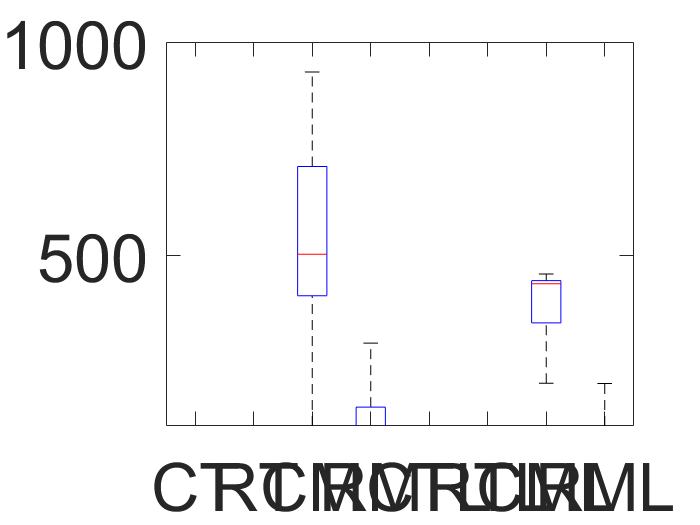


figure
Ac = boxplot(xs,gs,'symbol','');
hold on
P = yline(PoltringenH,'-','LineWidth',2);
T = yline(TailfingenH,'--','LineWidth',2);
set(gca,'FontSize',40,'TickLength',[0.030 0.015]) 
ylim([100 1000])
box on
hold off

## Supplementary Figure S1

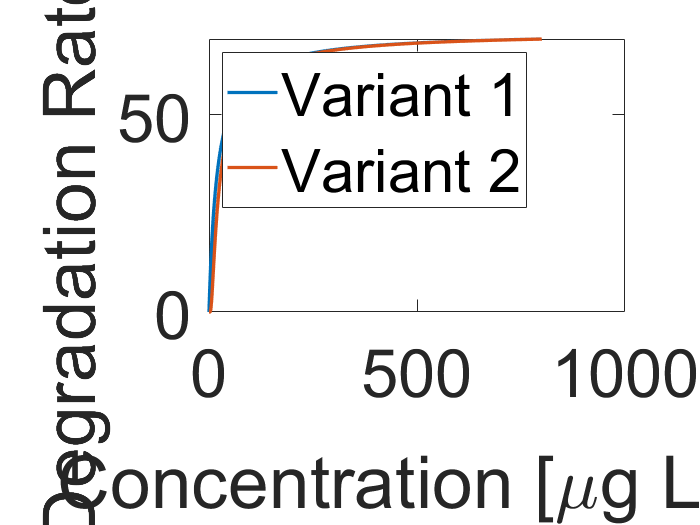

k_m_h = 71;
K_m_h = 20;

C_HYc = linspace(0,800,800);

figure
MonC = plot(C_HYc,k_m_h*C_HYc.*(K_m_h+C_HYc).^(-1),'LineWidth',2);
hold on
therC  = plot(C_HYc,k_m_h.*exp(-K_m_h./C_HYc),'LineWidth',2);
set(gca,'FontSize',40,'TickLength',[0.030 0.015])
legend([MonC therC],'Variant 1','Variant 2','Location','northwest')
xlabel('Concentration [\mug L^{-1}]')
ylabel('Degradation Rate [d^{-1}]')
box on
hold off